# Wrong masses

In my experiment, I needed to measure the mass of all samples (contaning ice and magnetite). 

Unfortunatly, in one of the sessions of the experiment, when I came to measure the mass of the samples I found out that some of them where partly evaporated. In several cases I did not measure the mass at all, but also in the ones I did measure within this session the values might be wrong, so I estimate the error of those sample much larger than usual. 

In order to try to estimate the missing masses and to fix the wrong ones I used another measure called magnetic susceptibility which I measured before the evaporation. This represents the magnetite concentration within a sample (K real). 

The first figure show the mass of a sample vs. its susceptibility. Several sessions are shown (represented in different color for each magnetite concentration), and the one with the missing mass is easily noticeable, both by lower values than the rest and large errors. 

The idea here is to try and find a relation between the mass of a sample and its susceptibility. It make sense that generally the more mass a sample has, the more magnetite it contains, hence it has higher susceptibility. 

So first I calculated correlation coeficients matrix for each "good" session. 

% original masses:
load SamplesData_original_masses.mat
load colord %color order set
figure(1)
clf;hold on;grid on
ex12=m.ExperN~=3;
ex3=m.ExperN==3;
figure(1)
cons=unique(m.estConcentration);

cons =          0
    0.0001
    0.0010
    0.0050
    0.0100


for i=1:length(cons)
    ind = (ex12 & m.estConcentration==cons(i));
    h(i) = plotEllipse(gca,[m.Kre(ind),m.Mass(ind),m.dKre(ind),m.dMass(ind),zeros(sum(ind),1)],colord(i,:),colord(i,:),0.5,'');
    corrcoef(m.Kre(ind),m.Mass(ind))
    ind = (ex3 & m.estConcentration==cons(i));
    plotEllipse(gca,[m.Kre(ind),m.Mass(ind),m.dKre(ind),m.dMass(ind),zeros(sum(ind),1)],colord(i,:),colord(i,:)/3,0.5,'');
end

ans =     1.0000    0.2098
    0.2098    1.0000


ans =     1.0000   -0.9076
   -0.9076    1.0000


ans =     1.0000    0.5971
    0.5971    1.0000


ans =     1.0000    0.7467
    0.7467    1.0000


ans =     1.0000    0.2076
    0.2076    1.0000


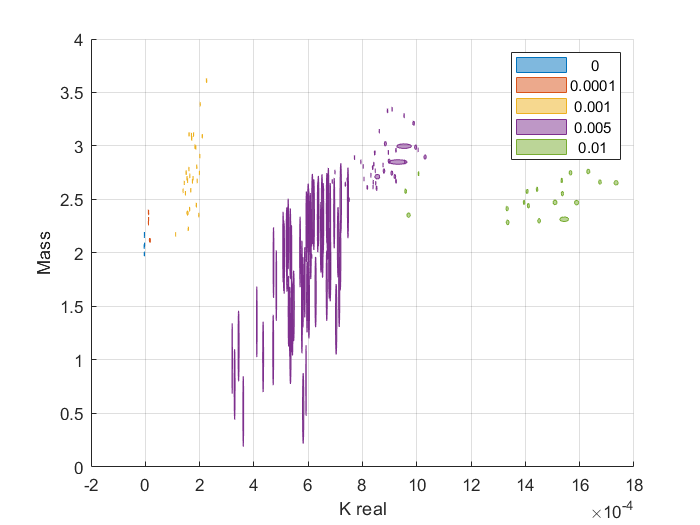

legend(h,num2str(cons))
ylabel('Mass')
xlabel('K real')
grid on

sprintf('+%d samples with missing mass', sum(isnan(m.Mass)))

ans = '+7 samples with missing mass'

## find linear fit - susc vs. mass:

Than I choose the one that gave the highest correlation and try to fit a linear relation. 

figure(3);clf;hold on
ex3=(m.ExperN==3);
ind = (ex12 & m.estConcentration==0.005 & ~isnan(m.Mass));
y=m.Mass(ind); x=m.Kre(ind);
% plot(x,y,'x');grid on
[a,F]=polyfit(x,y,1)

a = 	1.0e+03 *

    2.1334    0.0010


F = struct with fields:
        R: [2×2 double]
       df: 42
    normr: 1.3132


% fplot(@(Z) a(1)*Z+a(2),xlim);
% set(gca,'xs','log','ys','log')
% llfit
%0.00026138 +/- 3.5924e-05

## check each batch

One session contains several 'batches' of samples. I show here the original "wrong" masses (colors, by batches) and the expected masses by the above linear relation (black ellipses). 

figure(2);clf;hold on
ex3=(m.ExperN==3);
ex3 = (ex3 & contains(m.SampleName,"M"))

ex3 = 173×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


batches=unique(m.SampleName(ex3))

batches = 5×1 string array
    "Ma"
    "Mc"
    "Md"
    "Me"
    "Mf"


[Mass_fit,Mass_err]=polyval(a,m.Kre,F);
clear h h2
h2 = plotEllipse(gca,[m.Kre(ex3),Mass_fit(ex3),m.dKre(ex3),Mass_err(ex3),zeros(sum(ex3),1)],'k','k',0.1,'');
for i=1:length(batches)
    ind = (ex3 & m.SampleName==batches(i));
    h(i)=plotEllipse(gca,[m.Kre(ind),m.Mass(ind),m.dKre(ind),m.dMass(ind),zeros(sum(ind),1)],colord(i,:),colord(i,:),0.5,'');
    sprintf('Batch %s: %d samples with missing mass', batches(i),sum(isnan(m.Mass(ind))))
end

ans = 'Batch Ma: 3 samples with missing mass'

ans = 'Batch Mc: 1 samples with missing mass'

ans = 'Batch Md: 0 samples with missing mass'

ans = 'Batch Me: 0 samples with missing mass'

ans = 'Batch Mf: 1 samples with missing mass'

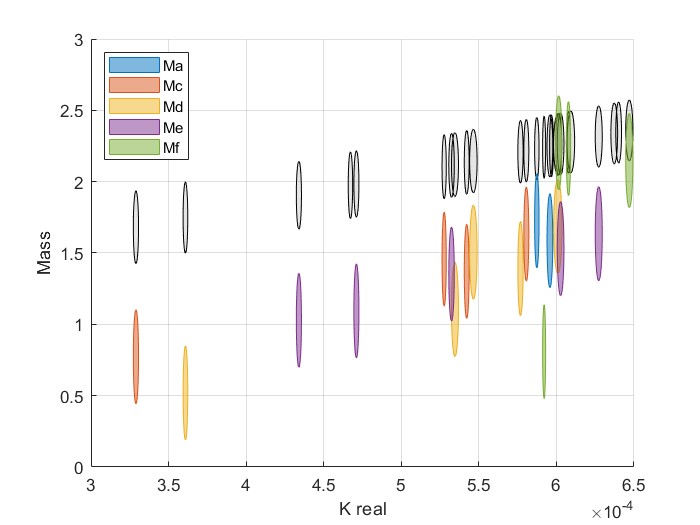

legend(h,batches,'location','nw');

grid on
ylabel('Mass')
xlabel('K real')

% fplot(@(Z) a(1)*Z+a(2),xlim, 'DisplayName','ex. 1&2 fit');

## adding the missing masses:

ex3=(m.ExperN==3);
ind_mis = (ex3 & m.estConcentration==0.005 & isnan(m.Mass));
m.Mass(ind_mis) = Mass_fit(ind_mis);
m.dMass(ind_mis) = Mass_err(ind_mis);

% and fix the wrong masses:
ind_fix = (ex3 & m.estConcentration==0.005 & m.Mass<(Mass_fit-Mass_err));
m.Mass(ind_fix) = Mass_fit(ind_fix);
m.dMass(ind_fix) = Mass_err(ind_fix);

figure(3);clf;hold on
ex3=(m.ExperN==3);
ex3 = (ex3 & contains(m.SampleName,"M"))

ex3 = 173×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


batches=unique(m.SampleName(ex3))

batches = 5×1 string array
    "Ma"
    "Mc"
    "Md"
    "Me"
    "Mf"


[Mass_fit,Mass_err]=polyval(a,m.Kre,F);
clear h h2
h2 = plotEllipse(gca,[m.Kre(ex3),Mass_fit(ex3),m.dKre(ex3),Mass_err(ex3),zeros(sum(ex3),1)],'k','k',0.1,'');
for i=1:length(batches)
    ind = (ex3 & m.SampleName==batches(i));
    h(i)=plotEllipse(gca,[m.Kre(ind),m.Mass(ind),m.dKre(ind),m.dMass(ind),zeros(sum(ind),1)],colord(i,:),colord(i,:),0.5,'');
    sprintf('Batch %s: %d samples with missing mass', batches(i),sum(isnan(m.Mass(ind))))
end

ans = 'Batch Ma: 0 samples with missing mass'

ans = 'Batch Mc: 0 samples with missing mass'

ans = 'Batch Md: 0 samples with missing mass'

ans = 'Batch Me: 0 samples with missing mass'

ans = 'Batch Mf: 0 samples with missing mass'

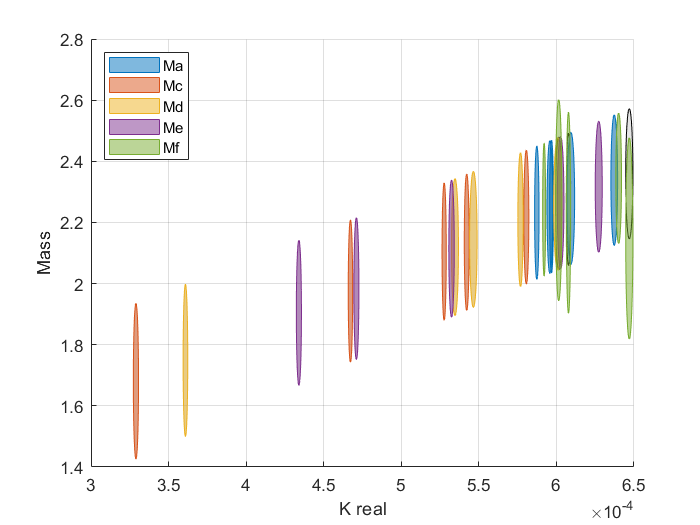

legend(h,batches,'location','nw');

grid on
ylabel('Mass')
xlabel('K real')

## re-calculate normalized magnetization and errors

%determine nominal susceptibility value to normalize to:
a_ind=find(m.estConcentration==0.005 & m.particleType==2); %group a
b_ind=find(m.estConcentration==0.005 & m.particleType==1); %group b
chi0a = mean(m.Susc(a_ind));
chi0b = mean(m.Susc(b_ind));
clear x dx y dy
tic
for i=find(ind_mis | ind_fix)'
    sample = [char(m.SampleName(i,:)) num2str(m.SampleNum(i))]
    [Kre, dKre, chi, dchi] = choose_susc(sample, m.ExperN(i), m.Mass(i), m.dMass(i));
    m.Kre(i) = Kre;
    m.dKre(i) = dKre;
    m.Susc(i) = chi;
    m.dSusc(i) = dchi;
    if m.particleType(i)==2
        chi0 = chi0a;
    else
        chi0 = chi0b;
    end
    y = m.Mint(i)/m.Mass(i); % normalize by mass to emu/g = Am^2/kg
    f = @(x) x(1,:)./x(2,:);
    x(1) = m.Mint(i); dx(1) = m.Mdint(i);
    x(2) = m.Mass(i); dx(2) = m.dMass(i);
    [y1, dy] = cal_MT_err(x, dx, f, 0);
    if abs(y-y1)/y>0.01 & m.Mint(i)>10*min(m.Mint), error(['Problem with calculation of error in sample ', num2str(i)]); end
    m.Mint_mass(i) = y;
    m.Mdint_mass(i) = dy;
    
    y = y .* chi0/m.Kre(i); % normalize by susciptibility(mass), and multiply by nominal value for correct units
    f = @(x) x(1,:)./x(2,:) .* chi0./x(3,:);
    x(1) = m.Mint(i); dx(1) = m.Mdint(i);
    x(2) = m.Mass(i); dx(2) = m.dMass(i);
    x(3) = m.Kre(i); dx(3) = m.dKre(i);
    [y1, dy] = cal_MT_err(x, dx, f, 0);
    if abs(y-y1)/y>0.01, error(['Problem with calculation of error in sample ', num2str(i)]); end
    m.Mint_susc(i) = y;
    m.Mdint_susc(i) = dy;
end

sample = 'Da0'

sample = 'Da1'

sample = 'Da2'

sample = 'Da4'

sample = 'Db0'

sample = 'Db4'

sample = 'Dc0'

sample = 'Dd0'

sample = 'Ia3'

sample = 'Ib2'

sample = 'Ib3'

sample = 'Ib4'

sample = 'Ic2'

sample = 'Ic3'

sample = 'Ic4'

sample = 'Id1'

sample = 'Id2'

sample = 'Md0'

sample = 'Md1'

sample = 'Md2'

sample = 'Md3'

sample = 'Md4'

sample = 'Me0'

sample = 'Me1'

sample = 'Me2'

sample = 'Me3'

sample = 'Me4'

sample = 'Ma0'

sample = 'Ma1'

sample = 'Ma2'

sample = 'Ma3'

sample = 'Ma4'

sample = 'Mc0'

sample = 'Mc1'

sample = 'Mc2'

sample = 'Mc3'

sample = 'Mc4'

sample = 'Mf3'

sample = 'Mf4'

toc

Elapsed time is 12.064816 seconds.


save('SamplesData_mass_fixed.mat','m')